We consider the IVP $u'=\sin[(u+t)^2]$ over $0\le t \le 4$, with $u(0)=-1$. 

f = @(t,u) sin( (t+u).^2 );
a = 0;  b = 4;
u0 = -1;

We use the built-in solver `ode113` to construct an accurate approximation to the exact solution.

opt = odeset('abstol',5e-14,'reltol',5e-14); 
uhat = ode113(f,[a,b],u0,opt);
u_exact = @(t) deval(uhat,t)';

Now we perform a convergence study of our two Runge--Kutta implementations.

n = 50*2.^(0:5)';
err_IE2 = 0*n;
err_RK4 = 0*n;
for j = 1:length(n)
    [t,u] = ie2(f,[a,b],u0,n(j));
    err_IE2(j) = max(abs(u_exact(t)-u));
    [t,u] = rk4(f,[a,b],u0,n(j));
    err_RK4(j) = max(abs(u_exact(t)-u));
end

The amount of computational work at each time step is assumed to be proportional to the number of stages. Let's compare on an apples-to-apples basis by using the number of $f$-evaluations on the horizontal axis.

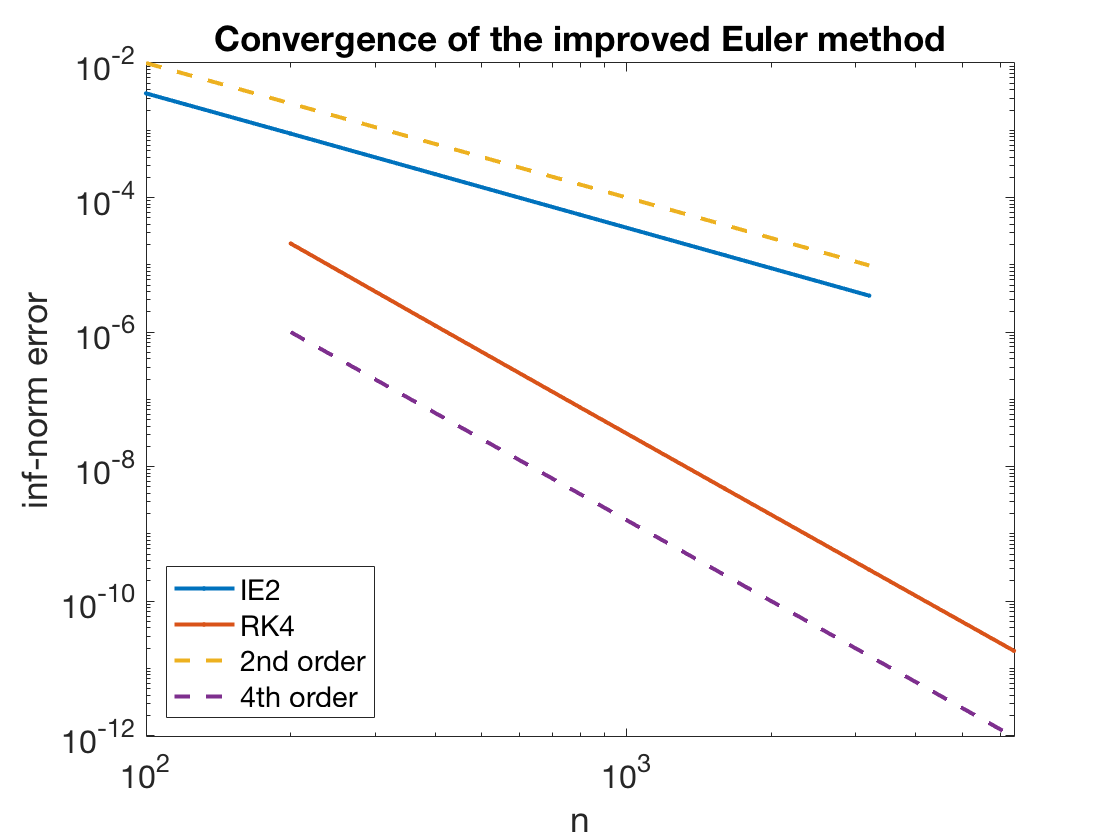

loglog(2*n,err_IE2,'.-')
hold on, loglog(4*n,err_RK4,'.-')
loglog(2*n,0.01*(n/n(1)).^(-2),'--')
loglog(4*n,1e-6*(n/n(1)).^(-4),'--')
xlabel('n'), ylabel('inf-norm error')  % ignore this line
title('Convergence of the improved Euler method')  % ignore this line
axis tight  % ignore this line
legend('IE2','RK4','2nd order','4th order','location','southwest')  % ignore this line

The fourth-order variant is more efficient in this problem over a wide range of accuracy.